# Arctic Sea Ice

[⇦ Overview](matlab: OpenOverview)

**Learning Goals**

- Load and display Arctic sea ice extent GeoTIFF data.

- Quantify Arctic sea ice extent using logical operators.

- Use a for loop to analyze changes to Arctic sea ice from 1979 to 2021.

- Compute the linear trend of Arctic sea ice extent.

## Arctic Sea Ice Observations

Global temperature increase has been proposed as the cause of several deleterious climatological and weather effects. One such effect is the decline of Arctic sea ice. Sea ice decline has several ramifications, including sea level rise and decreased albedo in regions where ice used to exist (albedo is the fraction of light reflected by a surface). Decreased albedo can, in turn, cause more radiation to be absorbed, further warming the planet. This effect is known as ice-albedo feedback.

## 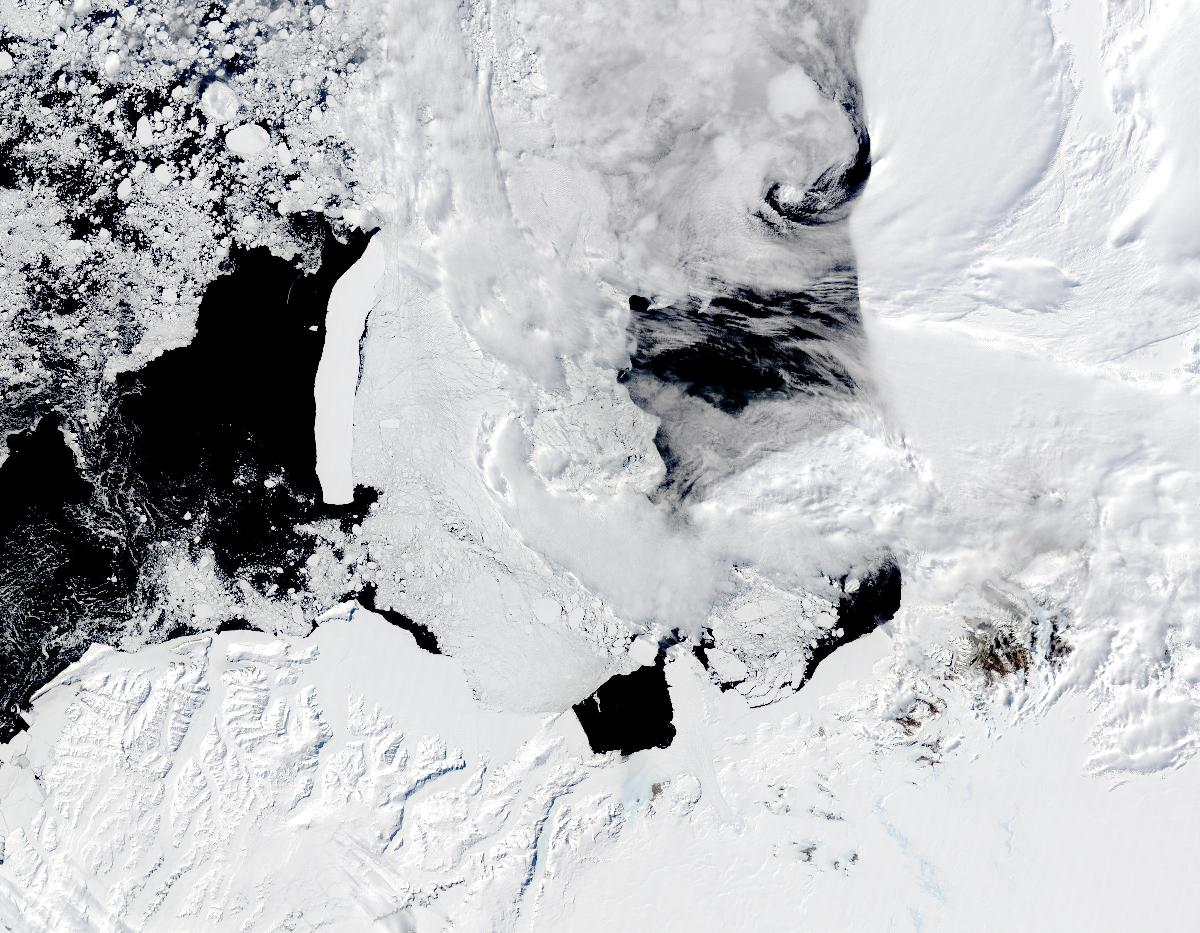

*Iceberg in the Ross Sea, Antarctica. Image courtesy of the NASA Visible Earth collection *[1]*.*

In this live script, you will explore Arctic sea ice data. The data is from the Sea Ice Index, Version 3, courtesy of the National Snow and Ice Data Center (NSIDC) [2]. This data is freely available from the NSIDC and can be downloaded [here](https://nsidc.org/data/G02135/versions/3).

   **Example. **Run this section to read and display the Arctic sea ice extent in September 2021. This example illustrates how you can read a data image and its colormap into MATLAB and display it.

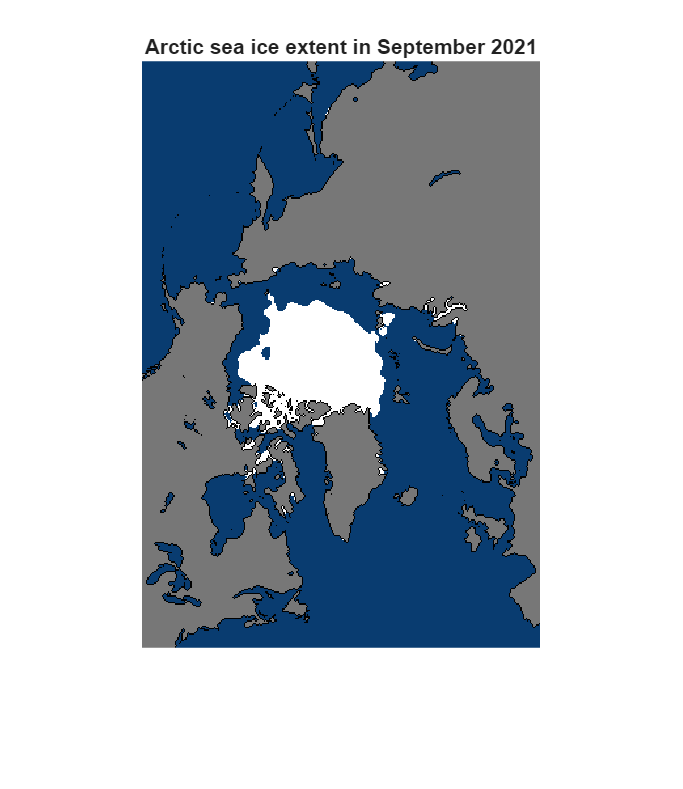

DataFile = "N_202109_extent_v3.0.tif";
[I,cmap] = imread(DataFile);
imshow(I,cmap)
title("Arctic sea ice extent in September 2021")

The extent of the Arctic sea ice is generally low in September due to melting during the summer. In other months, greater sea ice extent can be observed.

    **Activity. **In this activity, you will read and display the sea ice extent measured in different months and years.

**Task 1**. Read and display the Arctic sea ice extent data from February of 2021. The data files are named with the format:

`    N_YYYYMM_extent_v3.0.tif`

The YYYY and MM are replaced with the 4-digit year and 2-digit month.

**Hint: **Copy and modify the code from the previous example.

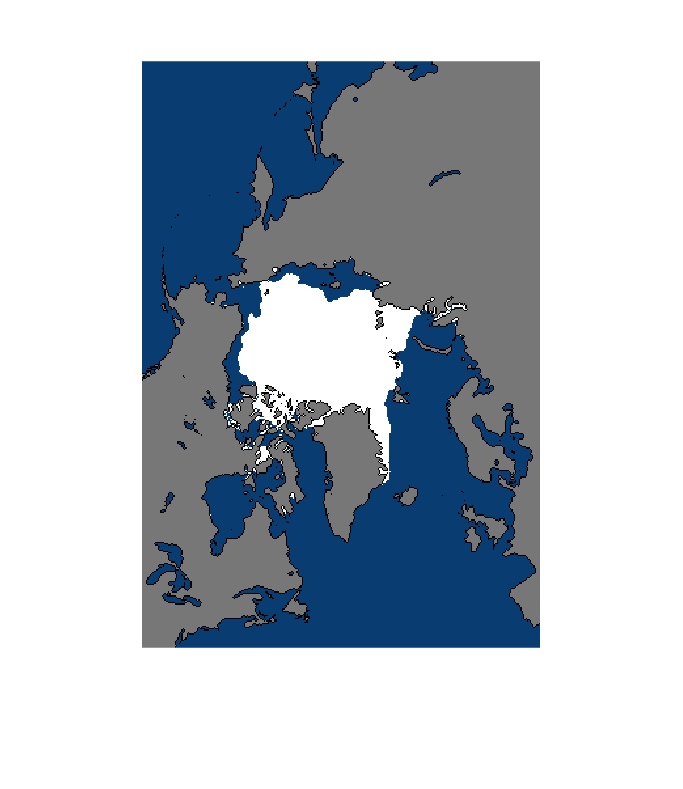

% Write your code here
% DataFile = "N_202102_extent_v3.0.tif";
DataFile = "N_198109_extent_v3.0.tif";
[I,cmap] = imread(DataFile);
imshow(I,cmap)

**Task 2. **Comparing the extent of the Arctic sea ice between winter and summer months isn't especially relevant for analyzing climate change. Instead, you'll want to compare data from different years. Modify the code above to read the Arctic sea ice extent data from September 1981. How does it compare to the sea ice extent observed forty years later (but earlier in this script) in September 2021?

## Quantifying Extent

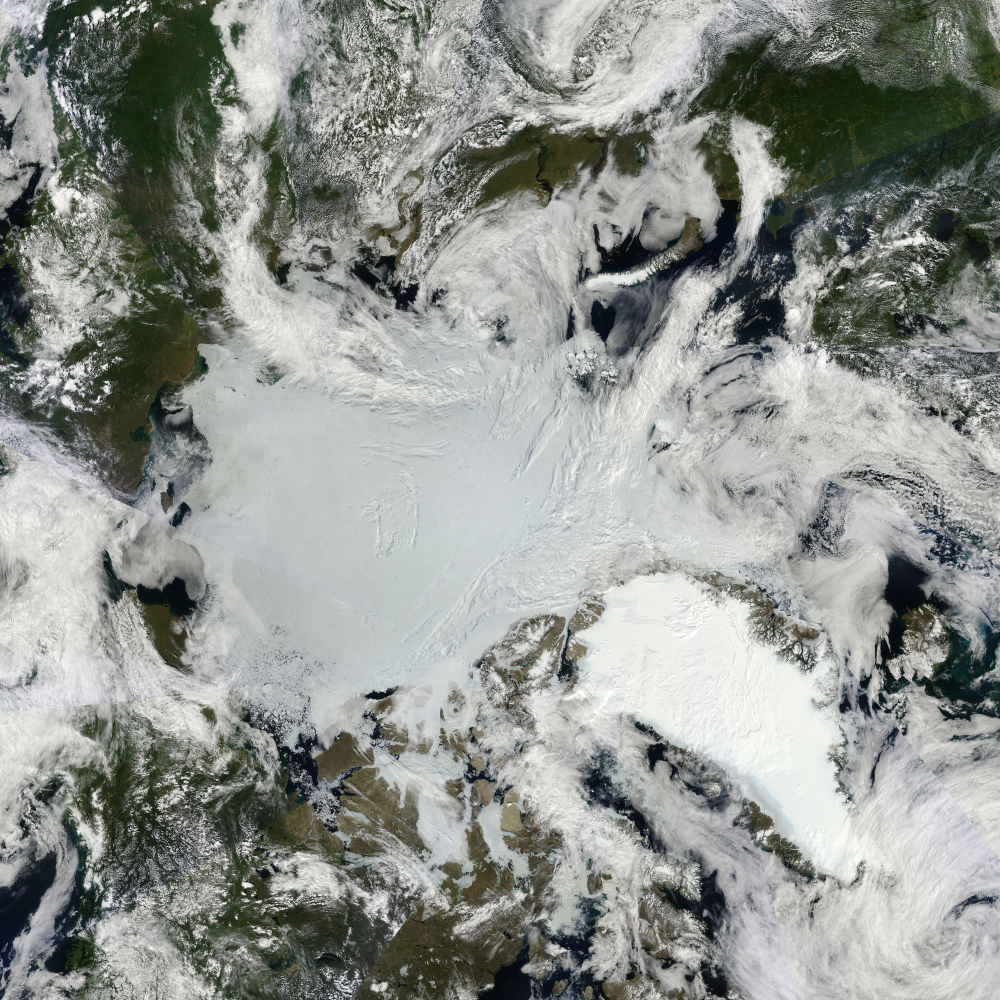

*Sunny skies over Arctic sea ice. True color image from the Moderate Resolution Imaging Spectroradiometer (MODIS) onboard Nasa's Terra satellite. Acquired July 11, 2011. NASA image courtesy *[*MODIS Rapid Response Team*](http://rapidfire.sci.gsfc.nasa.gov/)* at NASA GSFC. *[3]

Clearly, there is more sea ice in the winter than at the end of summer. It also appears that there is more ice in 1981 than in 2021. But how much more? In other words: what is the extent of the Arctic sea ice at each point in time? To find out, you can count the number of sea ice pixels in each GeoTIFF image and then multiply them by the physical area represented by each pixel.

   **Activity. **In this activity, you will compute the extent of the Arctic sea ice in September 1981 from GeoTIFF data.

**Task 1. **Copy your code from the last example to read the image data for September 1981. Then, run this section to reload the data.

DataFile = "N_198109_extent_v3.0.tif";
[I,cmap] = imread(DataFile);
imshow(I,cmap)

**Task 2. **Although the data is displayed in color, it actually contains only an $n \times m$ matrix of values (rather than an $n \times m \times 3$ array, the size of a typical RGB color image). Verify this by computing the size of the image data `I` you created in **Task 1** using the [`size`](https://www.mathworks.com/help/matlab/ref/size.html) function.

size(I)

ans =    448   304


**Task 3. **The image data classifies different regions using various pixel values. For example, the ocean pixels have a value of 0.

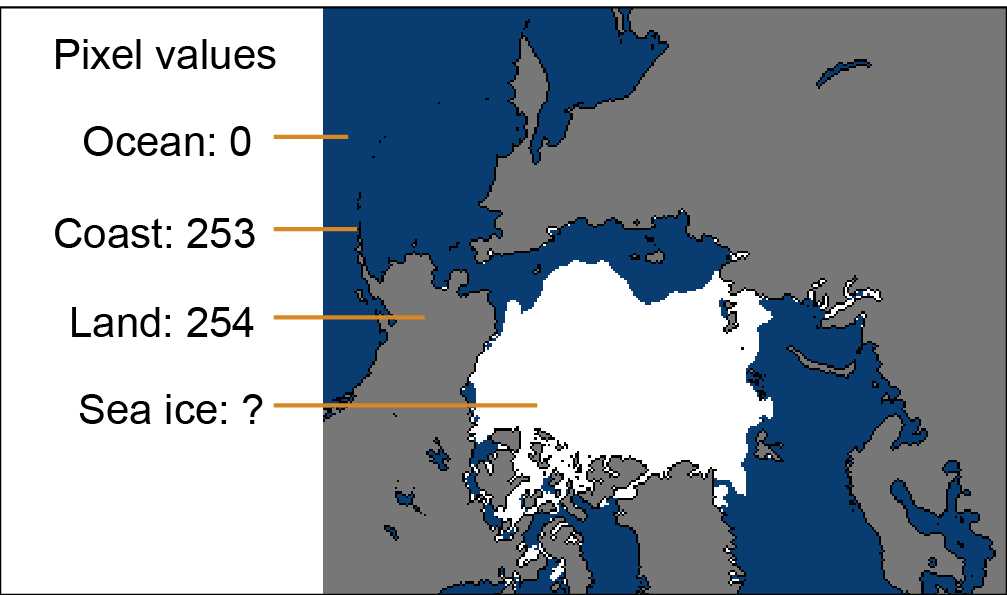

*Pixel values in the sea ice data *[3]*.*

What value represents sea ice? Store your answer below in IceValue.

**Hint:**

- Pop out the figure you created in **Task 1** by hovering over the image and then clicking .

- In the figure window, hover over the image and select the data tooltip  . Then, click on the ice. The **index **gives the value of the data array at the clicked location.

IceValue = 1;

**Task 4. **Identify all the pixels that are ice and store the result in a variable named `ice`. To do so, compare the image data array `I` to IceValue using the logical [`==`](https://www.mathworks.com/help/matlab/ref/eq.html) operator. For example, to find all the ocean points, you would use

ice = I == IceValue;

**Task 5. **The logical `==` operator returns a logical array that is 1 where the statement is true and 0 elsewhere. To identify the total number of pixels that contain ice, use the `nnz` function to count the number of non-zero values in the array `ice`. Store the result in NumIce. 

NumIce = nnz(ice)

NumIce = 11136

**Task 6. **Each pixel of the map represents an area of 25 $\times$ 25 km (as mentioned in the metadata [here](https://nsidc.org/data/G02135/versions/3)). Compute the total area of sea ice in km$^2$ and store the result in IceArea1981.

IceArea1981 = NumIce*25*25

IceArea1981 = 6960000

 **Exercise. **In this exercise, you will compare the Arctic ice area in September 1981 to the extent present in September 2021.

**Question 1. **What is the total ice area measured in September 2021? Store your result in a variable named IceArea.

**Hint: **Follow similar steps to those used in the previous activity.

DataFile = "N_202109_extent_v3.0.tif";
[I,cmap] = imread(DataFile);
ice = I == 1;
NumIce = nnz(ice);
IceArea2021 = NumIce*25^2

IceArea2021 = 4796875

**Question 2. **By what percentage did the ice area decrease between September 1981 and 2021? Store your result in a variable named IceLoss. The formula for percent loss is


$$\text{\% Loss}= \frac{\text{Initial value} - \text{Final value}}{|\text{Initial value}|} \cdot 100\%$$


IceLoss = 100*(IceArea1981 - IceArea2021)/IceArea1981

IceLoss = 31.0794

## Recent History

The calculation performed in the prior section illustrates that there was approximately 30% less ice area in September 2021 than there was in September 1981. Because weather is inherently unpredictable, this could simply be a result of yearly variations. If so, this would be an example of cherry picking data.

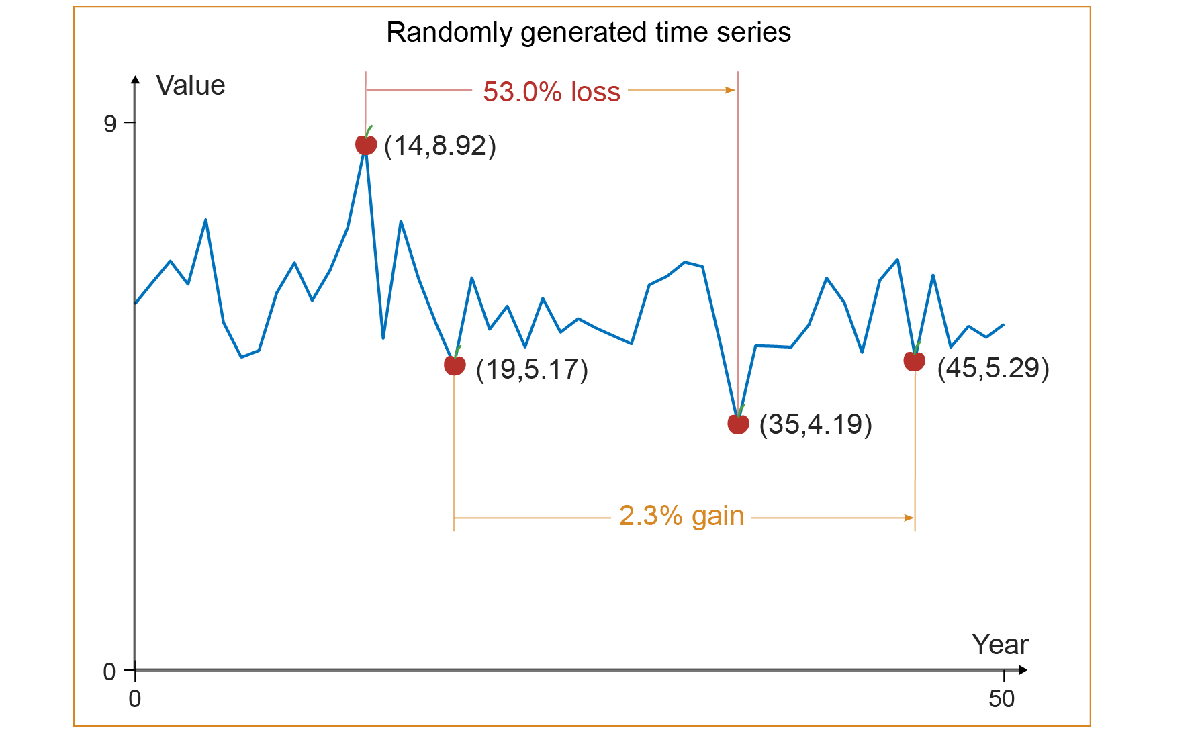

*Example of cherry picking from random data (this graph does not plot sea ice area and is simply an illustration of cherry picking). From this data, you could claim that over a 21 year period, the variable experienced a 53% loss. Another valid claim would be a 2.3% gain over 26 years. While both are technically true, using these claims independently from the full dataset could easily mislead an unsuspecting reader.*

To understand if the sea ice data was cherry-picked in the activity above, you can plot the time series of the Arctic sea ice extent during September of each year. This will illustrate if there does indeed appear to be a long-term trend present in Arctic sea ice extent.

   **Example. **Run this section to display the Arctic sea ice extent during September of each year from 1979 to 2021. This example illustrates how you can use a datastore and for loop to load and display all the image files in a folder.

% Read the images for September
ProjectRoot = currentProject().RootFolder;
ds = datastore(fullfile(ProjectRoot,"Data/SeaIce/September"),"FileExtensions",".tif","Type","image");
% Pop out a figure window
f = figure("Visible","on"); 
for k = 1:numel(ds.Files)
    % Read the image and display it
    [I,cmap] = imread(ds.Files{k});
    imshow(I,cmap);
    % Add a title
    [~,name,ext] = fileparts(ds.Files{k});
    DateString = extractBetween(name,"N_","09_extent");
    title("Sea ice extent from September " + DateString,"Interpreter","None");
    pause(0.1)
end
close(f)

    **Activity. **In this activity, you will compute the extent of the Arctic sea ice in September of each year from 1979 to 2021.

**Task 1. **The GeoTIFF files for the Sea Ice Index, Version 3 [2] for September of each year from 1979 to 2021 are included in the folder: 

`       Data/SeaIce/September/`

To obtain a list of the files in that directory, you can create a [`datastore`](https://www.mathworks.com/help/matlab/ref/datastore.html) using the syntax: 

Perform this operation and store the output in DsSepte`mber`. Forgo the semicolon so that you can see the properties of the datastore.

DsSeptember = datastore(fullfile(currentProject().RootFolder,"Data","SeaIce","September"),"FileExtensions",".tif","Type","image")

DsSeptember =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\SeaIce\September\N_197909_extent_v3.0.tif';
                              ' ...\Data\SeaIce\September\N_198009_extent_v3.0.tif';
                              ' ...\Data\SeaIce\September\N_198109_extent_v3.0.tif'
                               ... and 40 more
                              }
                     Folders: {
                              ' ...\MCC\climate-data-visualization-and-analysis\Data\SeaIce\September'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


**Task 2. **The datastore contains the location of the files in the `Files` property. You can access the `Files` property using the syntax: 

Count the number of files in the datastore using the [`numel`](https://www.mathworks.com/help/matlab/ref/double.numel.html) function, and store the result in `NFiles`.

NFiles = numel(DsSeptember.Files)

NFiles = 43

**Definition: **A **row **vector is a 1 x N array. For example:

    
$$a  = \left[ \matrix{ 1 & 2 & 3 & 4 & 5 } \right]$$


**Definition: **A **column **vector is an N x 1 array. For example: 

    
$$b = \left[ \matrix{ 1 \cr 2 \cr 3 \cr 4 \cr 5 } \right]$$


**Task 3. **Create a **column** vector named `years` that contains the years from 1979 to 2021 (inclusive). You can create a **row** vector that counts by 1s using the [colon (:)](https://www.mathworks.com/help/matlab/ref/colon.html) operator. For example, to create a row vector `a = [1 2 3 4 5]`, you could use:

Vectors created using the colon operator are **row** vectors. Use the [transpose operator (')](https://www.mathworks.com/help/matlab/ref/transpose.html) to convert it into a **column** vector. For example, 

years = (1979:2021)'

years =         1979
        1980
        1981
        1982
        1983
        1984
        1985
        1986
        1987
        1988


**Task 4. **Use a [`for` loop](https://www.mathworks.com/help/matlab/ref/for.html) to loop through all the files in the datastore DsSeptember. Compute the sea ice extent for each image read and store the results in a vector named IceArea. You can write your own code or follow the listed steps to complete the for loop.

- Create a column vector of zeros with `NFiles` entries and name the vector IceArea. Use the [`zeros`](https://www.mathworks.com/help/matlab/ref/zeros.html) function with the syntax `zeros(n,m)`, where `n` is the number of rows and `m` is the number of columns. Your vector IceArea should have `Nfiles` rows and one column.

- Create a [`for` loop](https://www.mathworks.com/help/matlab/ref/for.html) with an index variable `k`. The loop should start at `1` and end at `NFiles`. Don't forget the closing keyword: `end`. If you're having difficulty creating the loop, refer to this example.

- Inside the for loop, read the `kth` image from the datastore using the [`readimage`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.readimage.html) function with the syntax `readimage(ds,k)`, where `ds` is the datastore. Store the result in `imgk`.

- Using the code you wrote in the previous exercise, compute the ice area in the `k`th image. Assign the result to the kth entry of the vector IceArea. **Hint:** You can assign to the `k`th entry of a vector `v` using the syntax: `v(k) = value`.

IceArea = zeros(NFiles,1);
for k = 1:NFiles
    imgk = readimage(DsSeptember,k);
    ice = imgk == 1;
    NumIce = nnz(ice);
    IceArea(k) = NumIce*25^2;
end

**Task 5. **Plot the vector IceArea (created in **Task 4**) against the vector `years` (created in **Task 3**). Give appropriate labels to the axes and a title (use [`xlabel`](https://www.mathworks.com/help/matlab/ref/xlabel.html), [`ylabel`](https://www.mathworks.com/help/matlab/ref/ylabel.html), and [`title`](https://www.mathworks.com/help/matlab/ref/title.html)).

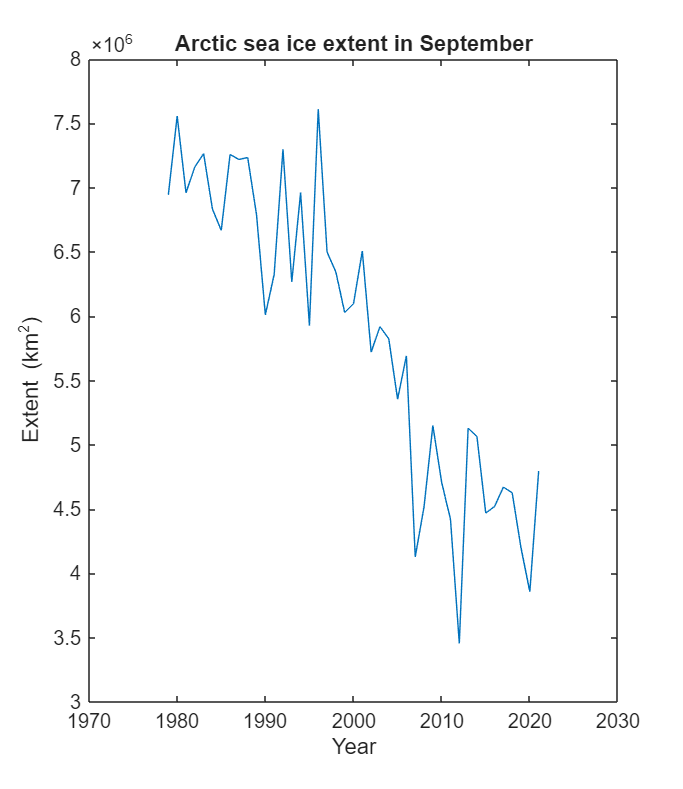

plot(years,IceArea)
xlabel("Year")
ylabel("Extent (km^2)")
title("Arctic sea ice extent in September")

## Trends

The data plotted in the previous activity shows a general decline in Arctic sea ice over the last 40 years. If the downward trend continues, Arctic ice could disappear entirely in future summers. 

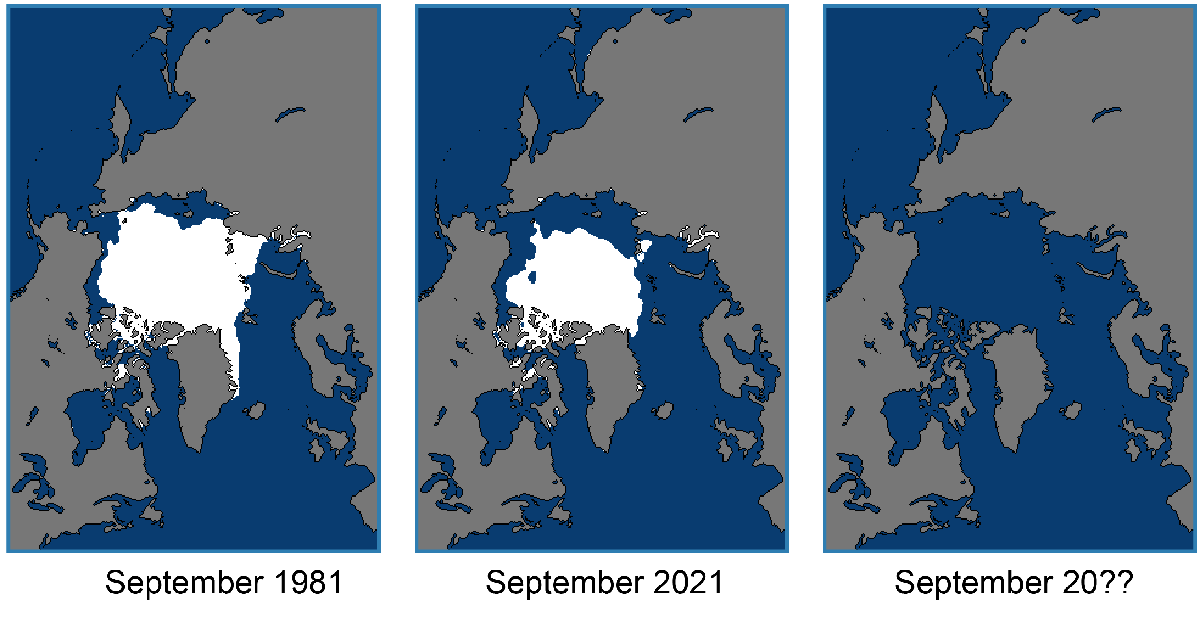

*Arctic sea ice extent in September. In which year will the sea ice disappear entirely?*

   **Activity. **In this activity, you will compute the linear trend of the Arctic sea ice extent. Then, you will identify during which year the linear trend predicts that the Arctic sea ice will vanish in the summer.

**Task 1. **In the previous activity, you created two variables that contain Arctic sea ice extent data: `years` and IceArea. You can compute the linear fit of this time-series data using the `fit` function with the syntax:

In this syntax, `t` and `y` are the independent and dependent variables, respectively. The third input, `"poly1"`, specifies a first-order polynomial fit (i.e., a straight line). Use the `fit` function to create a linear fit of the sea ice time-series data and store the result in IceFit. Forgo the semicolon to view the contents of the IceFit object.

**Note**: The fit function requires column vectors. If you see the error "X must be a matrix with one or two columns," your data may contain row vectors. Check the size of the vectors `years` and IceArea. If either is a row vector, transpose it using the [transpose operator (')](https://www.mathworks.com/help/matlab/ref/transpose.html).

IceFit = fit(years,IceArea,"poly1")

IceFit =      Linear model Poly1:
     IceFit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -8.176e+04  (-9.475e+04, -6.877e+04)
       p2 =   1.694e+08  (1.434e+08, 1.954e+08)

**Task 2. **Plot the fitted curve contained in IceFit together with the data. 

- Start by plotting the data contained in `years` and IceArea`.`

- Then, use the [`hold on`](https://www.mathworks.com/help/matlab/ref/hold.html) command to continue plotting on the same axes.

- Plot the fitted curve by using the `plot` function with only one input: the fit object IceFit.

- Add `hold off` to stop plotting on the same axes.

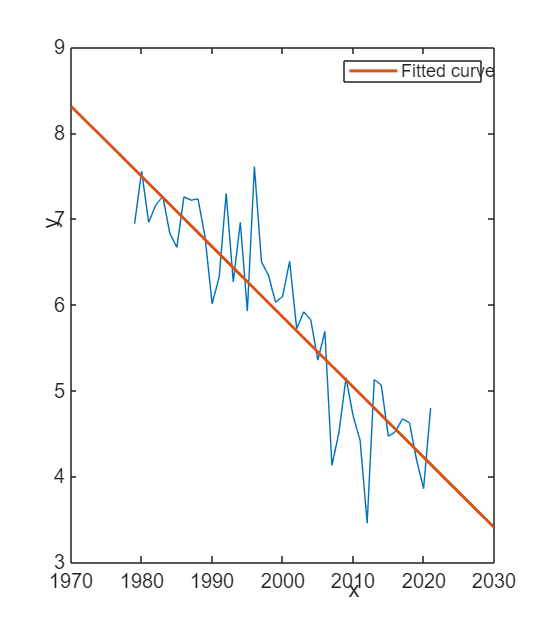

plot(years,IceArea)
hold on
plot(IceFit)
hold off

**Task 3. **Display the contents of the fit object IceFit. You should notice that it contains a linear model `p1*x + p2`. The coefficients p1 and p2 are stored in fields of the object. You can access them using the dot notation (e.g., IceFit`.p1`). Extract the coefficients and store them in new variables `p1` and `p2`.

p1 = IceFit.p1

p1 = -8.1762e+04

p2 = IceFit.p2

p2 = 1.6938e+08

**Task 4. **In which year does the linear trend predict zero ice area? You can calculate this by setting the linear function to zero (`p1*x + p2 = 0`) and then solving for the value of x (which, in this case, represents the year when the ice area is predicted to be zero). Store your answer below in the variable VanishYear. Use the [`round`](https://www.mathworks.com/help/matlab/ref/round.html) function to round your result to the nearest year.

VanishYear = round(-p2/p1)

VanishYear = 2072

[⇦ Overview](matlab: OpenOverview)

**References**

[1] Jacques Descloitres, MODIS Rapid Response Team, NASA/GSFC. Published January 3, 2003. C-19 iceberg in the Ross Sea, Antarctica. Accessed March 8, 2022 from [https://visibleearth.nasa.gov/images/63933/c-19-iceberg-in-the-ross-sea-antarctica](https://visibleearth.nasa.gov/images/63933/c-19-iceberg-in-the-ross-sea-antarctica).

[2] Fetterer, F., K. Knowles, W. N. Meier, M. Savoie, and A. K. Windnagel. 2017, updated daily. Sea Ice Index, Version 3. Northern sea ice extent subset. Boulder, Colorado USA. NSIDC: National Snow and Ice Data Center. doi: [https://doi.org/10.7265/N5K072F8](https://protect-us.mimecast.com/s/oz-ZC5yME6fnLED0IznV62?domain=doi.org). Accessed February 16, 2022.

[3] NASA image courtesy [MODIS Rapid Response Team](http://rapidfire.sci.gsfc.nasa.gov/) at NASA GSFC. Caption by Michon Scott. Accessed March 9, 2022 from [https://visibleearth.nasa.gov/images/51396/sunny-skies-over-arctic-sea-ice/51398l](https://visibleearth.nasa.gov/images/51396/sunny-skies-over-arctic-sea-ice/51398l).